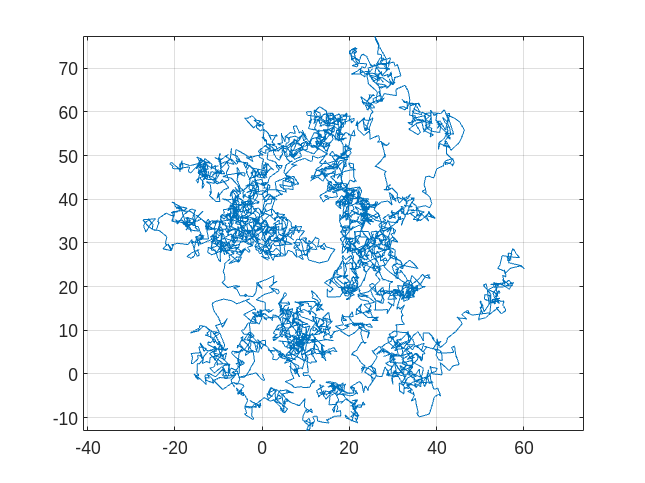

mu = [0;0];  % varhato ertekek (x,y szerint)
cc = 0;      % kereszt kovariancia
Sigma = [
    1 cc 
    cc 1
    ];       % kovariancia matrix

% Browm mozgas modell
obj = bm(mu,Sigma);

N = 5000;
y = simByEuler(obj,N);

fig = figure;
hold on, box on, grid on;
plot(y(:,1),y(:,2))
axis equal